## Note: this file will take a preprocessed EEG dataset, determine an appropriate baseline, and feed it into a Gaussian Mixture Model (GMM)

## read in filtered data

allEDFs_filtered = allEDFs; % TODO: change this so it reads in file for you

## BASELINE 

% find index of first instance of "intubat" (intubation)
index1 = find(contains(allEDFs_filtered.annotations{'EEG'}{:, 'Annotations'},'intubat', 'IgnoreCase',true));
onset1 = allEDFs_filtered.annotations{'EEG'}.Onset(index1(1,1));
[~, index] = ismember(allEDFs_filtered.data{'EEG'}.Time(:,1),onset1);
intubation_Index = find(index)

intubation_Index = 259585


% find index of first instance of "incis" (incision)
index2 = find(contains(allEDFs_filtered.annotations{'EEG'}{:, 'Annotations'},'incis', 'IgnoreCase',true));
onset2 = allEDFs_filtered.annotations{'EEG'}.Onset(index2(1,1));
[~, index] = ismember(allEDFs_filtered.data{'EEG'}.Time(:,1),onset2);
incision_Index = find(index)

incision_Index = 678529

% run function to determine start index for each EEG channel
channels = {'EEGFp1_Cp3','EEGFpz_Cp3', 'EEGCp3_T3', 'EEGT3_O1', 'EEGFp2_Cp4', 'EEGFpz_Cp4', 'EEGCp4_T4', 'EEGT4_O2'}

channels = 1×8 cell array
    {'EEGFp1_Cp3'}    {'EEGFpz_Cp3'}    {'EEGCp3_T3'}    {'EEGT3_O1'}    {'EEGFp2_Cp4'}    {'EEGFpz_Cp4'}    {'EEGCp4_T4'}    {'EEGT4_O2'}


table_size = size(allEDFs_filtered.data{'EEG'}); % determine size of table for for loop
start_index = nan(1,table_size(1,2));
for k = 1:length(channels) 
    % TODO: once "EEG_PreProcess.mlx" is complete, modify method for determining start index. 
    % all of those repeated values should become nan so we just need to take values after that point.
    start_index(1,k) = baseline_mean(table_size, allEDFs_filtered, channels(1,k));
end
start_index % check for baseline start

start_index =         4737        4737        4737        4737        4738        4737        4737        4737



% check that there is not a lot of variance between start_index values. too
% large of a difference could indicate a problem with the baseline
% determination values and would need to be evaluated on a case-by-case
% basis
diffs = diff(start_index);
diffs = max(abs(diffs(diffs >= 0)));
if (diffs > 5)
    error("large variance among baseline start indices detected. largest difference was determined to be " + diffs)
end

## baseline mean determination (single value/channel)

baseline_preIntubation = nan(1,8);
baseline_postIntubation = nan(1,8);
baseline_Total = nan(1,8);
for i = 1:table_size(1,2)
    baseline_preIntubation(1,i) = mean(allEDFs_filtered.data{'EEG'}{start_index(1,i):intubation_Index, channels(1,i)},'omitnan');  
    baseline_postIntubation(1,i) = mean(allEDFs_filtered.data{'EEG'}{intubation_Index:incision_Index, channels(1,i)},'omitnan');  
    baseline_Total(1,i) = mean(allEDFs_filtered.data{'EEG'}{start_index(1,i):incision_Index, channels(1,i)},'omitnan');
end
baseline_preIntubation

baseline_preIntubation =     0.0242   -0.0625   -0.0328    0.0620    0.1133   -0.0207   -0.0643   -0.0449


baseline_postIntubation

baseline_postIntubation =    -0.0609   -0.0633   -0.0908   -0.0123   -0.0346   -0.1700    0.0036   -0.0044


baseline_Total

baseline_Total =    -0.0387   -0.0631   -0.0757    0.0071    0.0040   -0.1311   -0.0141   -0.0150


## baseline mean determination (15 sec window/channel)


% 15 second windows
    % data from baseline regions is divided into 15 second windows and then
    % the mean is calculated to create one 15 second array per channel

rows_per_record = allEDFs_filtered.info{'EEG'}.NumSamples(1);    
sample_rate = rows_per_record/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration);   
window_size = sample_rate * 15;

preintubation_mean_baseline_window = mean_baseline_windowed(start_index, intubation_Index, allEDFs_filtered, window_size, channels)

preintubation_mean_baseline_window =     1.2978    0.0200    1.5495    1.2425   -0.3757   -0.4386    2.1100    4.0968
    1.5011    0.6168   -0.7610    2.8854    0.0322   -0.1354    3.8661   -0.4652
    0.6094    0.7536   -1.4075    1.9660   -1.3356   -0.2446    1.7213    0.4677
   -1.5589   -2.1768   -0.0676    0.7346   -3.4335   -1.8958   -2.0145    1.5812
   -3.1695   -3.3945    0.9323   -0.7787   -4.1893   -2.3434   -1.1438    0.3067
   -2.3840   -1.1769   -1.6624   -1.1462   -2.4030   -1.9814   -1.5908   -1.2766
   -0.9135   -1.2143   -2.1487   -2.1612   -0.5124   -2.1883   -2.5083   -1.4152
   -0.5667   -1.3250   -0.6608   -1.5753   -0.2680   -1.8591   -3.8172   -0.0776
   -0.2725   -0.7458   -0.5027   -0.3717   -0.6359   -0.8857   -0.2851   -1.9122
    0.1019    0.0876    0.4839    1.2008   -0.1455   -0.1998    0.2246    0.0269


postintubation_mean_baseline_window = mean_baseline_windowed(intubation_Index, incision_Index, allEDFs_filtered, window_size, channels)

postintubation_mean_baseline_window =     1.2132    0.0305   -1.9443   -0.4835    0.3248   -0.5629   -2.7228   -0.4128
    0.8137    0.1294   -1.9064   -0.2863   -0.9198   -0.4643   -2.2810   -0.1256
    0.6499   -0.1427   -1.5525   -0.2717   -0.8236   -0.8103   -2.2329    0.1960
    1.1459    0.1467   -1.5424   -0.3993    0.5455   -0.2289   -1.9702    0.0458
    1.3736    0.7846   -0.7380   -0.2476    0.7223   -0.4494   -1.3323   -0.0480
    1.7294    0.6218   -0.5058   -0.3226    1.3081    0.0154   -1.0675    0.0759
    1.7915    1.1175   -0.3579   -0.3854    1.8412    0.3146   -0.4856   -0.0978
    1.9908    1.7115   -0.0347   -0.2743    1.7262    0.9686   -0.4019    0.0170
    2.9963    2.7059   -0.7207   -0.6996    1.8255    0.9988   -0.5197   -0.3385
    3.4179    2.7159   -0.9955   -0.9914    1.8093    0.8587   -0.0324   -0.3595


total_mean_baseline_window = mean_baseline_windowed(start_index, incision_Index, allEDFs_filtered, window_size, channels)  

total_mean_baseline_window =    -0.4026   -0.9484    0.4276    0.3827   -0.5673   -0.7049    0.7572    0.7222
   -0.2907   -0.7456   -0.1898    0.6640   -0.9391   -1.5570    1.5681   -0.3852
   -0.3134   -0.4506   -0.3909    0.3211   -1.4155   -2.0278    1.3210   -0.2564
   -0.8831   -1.1281   -0.4033   -0.2100   -1.6715   -2.4225    0.4794    0.0076
   -1.3724   -1.1579   -0.6702   -0.8031   -1.6079   -2.5967    0.4336   -0.0637
   -0.8674   -0.3940   -1.5916   -0.8329   -0.5783   -1.8185   -0.3067   -0.1378
    0.0846    0.0400   -1.4820   -0.8934    0.5044   -0.9382   -0.7487    0.2045
    0.4752    0.3619   -0.7571   -0.6085    0.5206   -0.6449   -1.2571    0.4725
    0.8431    0.7006   -0.0774   -0.2941    0.5802   -0.1238   -0.1903   -0.2258
    1.2353    1.1521    0.1553    0.0275    0.9729    0.5068    0.2879    0.2493


## baseline window determination (3D - for GMM)

window_preintubation_baseline = windowed_data(start_index, intubation_Index, allEDFs_filtered, window_size,channels)

window_preintubation_baseline = window_preintubation_baseline(:,:,1) =

   -4.7729   26.5978   -6.6993    6.3439   -2.1840    9.8922   -4.1866   13.6536
    2.0571   27.0852   -6.8896   11.5978   -4.7424    9.8693   -8.3363   18.4201
   -5.7551   16.3415   11.1790   14.8947  -10.4836    8.4074   -8.0927    9.5039
   -9.6612    5.1104   13.3719   14.2856  -10.3617    6.9455    8.2627    9.1384
   -9.7830    4.6231   12.3973   10.2577   -7.0648    7.1891    5.3312    9.0242
  -14.1765   -2.7018   11.1790   10.1587   -6.2120    7.1510    9.7247   -9.6536
  -21.0141   -3.1282   11.6663    8.8186  -10.4836    3.9759   12.4125   -9.7450
   -9.2957   -1.6663    8.0038   10.4099   -4.0114    4.2043    6.3059   -3.0292
    6.3287    4.6840   -4.2018   12.2374    6.6104    7.1358   -2.9683    5.1485
   -8.8008    5.6587    4.8287   11.6282    5.7500   12.9912   -3.6993   11.6206
   -7.8262   -7.5216   11.9100   -4.8490    6.1155   13.1587   -4.6739    8.0800
   -6.8516   -8.0089   15.5724   -4.9

window_postintubation_baseline = windowed_data(intubation_Index, incision_Index, allEDFs_filtered, window_size,channels)

window_postintubation_baseline = window_postintubation_baseline(:,:,1) =

   -3.0977   -4.9556    9.1003   -2.8465    3.8921    2.6967    1.6003    6.3135
   -4.9252   -9.3566    8.3693   -3.2119    1.0825   -4.3845   -4.4988    6.2754
   -6.5165  -12.7678    6.1688   -5.1688   -2.8236   -8.5343   -9.6308    5.0571
   -7.8566  -14.7247   -8.7171   -6.6307   -7.7044  -13.9100  -13.2932   -2.5114
  -10.0572  -17.4125  -11.6485   -7.8490  -15.0293  -20.1308  -13.4531   -6.9049
  -11.8846  -19.3618  -11.6638   -8.3363  -20.6486  -25.2628  -12.2272  -10.3237
  -14.0851  -21.3186   -9.9582   -8.3516  -21.9887  -27.0902   -7.3465  -12.5166
  -16.2780  -23.5115   -7.2703   -7.4988  -21.7450  -27.0674   -6.1282  -13.3770
  -16.5217  -23.9989   -8.0013   -6.2805  -18.8136  -25.3618   -9.5470  -13.3846
  -16.4074  -23.7552  -10.6891   -5.7932  -15.1511  -21.9430  -12.9658  -11.7932
  -15.3110  -20.5877  -12.6384   -5.6561  -11.2450  -17.5496  -13.9404   -9.4785
  -13.3617  -15.9430  -12.8897   -5

window_total_baseline = windowed_data(start_index, incision_Index, allEDFs_filtered, window_size,channels)

window_total_baseline = window_total_baseline(:,:,1) =

   -4.7729   26.5978   -6.6993    6.3439   -2.1840    9.8922   -4.1866   13.6536
    2.0571   27.0852   -6.8896   11.5978   -4.7424    9.8693   -8.3363   18.4201
   -5.7551   16.3415   11.1790   14.8947  -10.4836    8.4074   -8.0927    9.5039
   -9.6612    5.1104   13.3719   14.2856  -10.3617    6.9455    8.2627    9.1384
   -9.7830    4.6231   12.3973   10.2577   -7.0648    7.1891    5.3312    9.0242
  -14.1765   -2.7018   11.1790   10.1587   -6.2120    7.1510    9.7247   -9.6536
  -21.0141   -3.1282   11.6663    8.8186  -10.4836    3.9759   12.4125   -9.7450
   -9.2957   -1.6663    8.0038   10.4099   -4.0114    4.2043    6.3059   -3.0292
    6.3287    4.6840   -4.2018   12.2374    6.6104    7.1358   -2.9683    5.1485
   -8.8008    5.6587    4.8287   11.6282    5.7500   12.9912   -3.6993   11.6206
   -7.8262   -7.5216   11.9100   -4.8490    6.1155   13.1587   -4.6739    8.0800
   -6.8516   -8.0089   15.5724   -4.9252   -7.4302   

## ANALYSIS 

% Note: from hospital team: abnormal events are annotated as alerts when duration
% of event exceeds 1 min

% from hospital team: abnormal events are observed when one or both
% hemishperes stray from baseline


## analysis window determination

window_analysis = windowed_data(intubation_Index+1, size(allEDFs_filtered.data{'EEG'}(:,1)), allEDFs_filtered, window_size,channels)

window_analysis = window_analysis(:,:,1) =

   -4.9252   -9.3566    8.3693   -3.2119    1.0825   -4.3845   -4.4988    6.2754
   -6.5165  -12.7678    6.1688   -5.1688   -2.8236   -8.5343   -9.6308    5.0571
   -7.8566  -14.7247   -8.7171   -6.6307   -7.7044  -13.9100  -13.2932   -2.5114
  -10.0572  -17.4125  -11.6485   -7.8490  -15.0293  -20.1308  -13.4531   -6.9049
  -11.8846  -19.3618  -11.6638   -8.3363  -20.6486  -25.2628  -12.2272  -10.3237
  -14.0851  -21.3186   -9.9582   -8.3516  -21.9887  -27.0902   -7.3465  -12.5166
  -16.2780  -23.5115   -7.2703   -7.4988  -21.7450  -27.0674   -6.1282  -13.3770
  -16.5217  -23.9989   -8.0013   -6.2805  -18.8136  -25.3618   -9.5470  -13.3846
  -16.4074  -23.7552  -10.6891   -5.7932  -15.1511  -21.9430  -12.9658  -11.7932
  -15.3110  -20.5877  -12.6384   -5.6561  -11.2450  -17.5496  -13.9404   -9.4785
  -13.3617  -15.9430  -12.8897   -5.0394   -8.3135  -13.2780  -13.8947   -7.3998
   -9.0902   -9.8440  -13.1333   -3.9429   -6.2424  -10.4683  -10


%gm = fitgmdist(preintubation_baseline_window, 1) % how do we know how many components a GMM should be?
%properties(gm); % list all properties for the GMM. Can be accessed using format "gm.NumVariables" (dot notation)
% for each 15 second window, for each channel compute delta (1-3Hz) theta
% (4-7Hz) alpha (8-12Hz) beta (13-20Hz) gamma (30-100Hz) (spectral) - 40 measurements for each window (40 X #15-second
% windows you have), then feed it into gaussian mixture model


## gaussian mixture model



Fs = allEDFs_filtered.info{'EEG'}.NumSamples(1,1)/seconds(allEDFs_filtered.info{'EEG'}.DataRecordDuration(1,1));   % sampling rate
L = length(window_analysis)

L = 1920

N = L % end point

N = 1920

f = (Fs*(0:((L-1)/2))/L); % frequency
transforms_analysis = fft(window_analysis, N, 1)/L; % returns each band being == 1Hz
single_sided_transform = transforms_analysis(1:L/2, :, :);
plot(f, single_sided_transform(:,1,1))

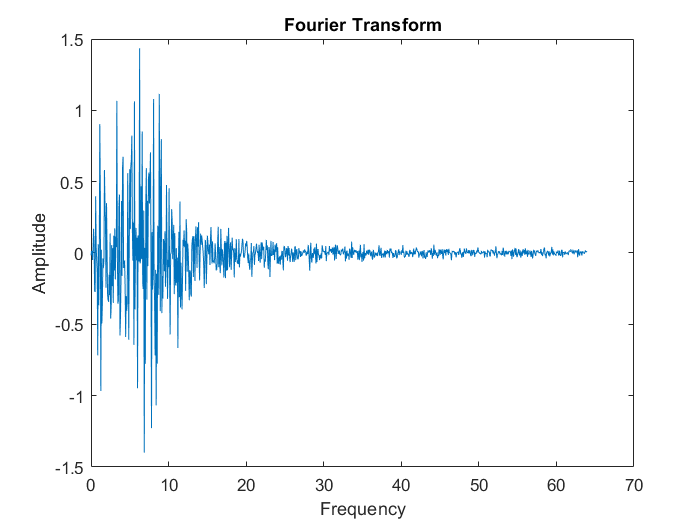

xlabel('Frequency')
ylabel('Amplitude')
title('Fourier Transform')

%delta = int(single_sided_transform(:,1,1),1,3)
%pspectrum(transforms_analysis(:,1,1), Fs)


% try to run bandpower function
% try 
%     for i = 1:size(window_analysis)(1,3)
%         delta = bandpower(window_analysis(:,:,i), Fs, [1 3]);
%         theta = bandpower(window_analysis(:,:,i), Fs, [1 3]);
%         alpha = bandpower(window_analysis(:,:,i), Fs, [1 3]);
%         beta = bandpower(window_analysis(:,:,i), Fs, [1 3]);
%         gamma = bandpower(window_analysis(:,:,i), Fs, [1 3]);
%     end
% catch ME
%     
% end
% z = fillmissing(window_analysis, 'movmedian', 10)
% delta = bandpower(window_analysis(:,:,4), Fs, [1 3])

% spectral bands
delta_analysis = spectral_bandpower(window_analysis, [1 3], Fs)

delta_analysis = 	1.0e+04 *

    0.0013    0.0018    0.0023    0.0010    0.0012    0.0026    0.0034    0.0020
    0.0011    0.0016    0.0026    0.0008    0.0024    0.0037    0.0037    0.0009
    0.0011    0.0018    0.0028    0.0009    0.0012    0.0016    0.0026    0.0015
    0.0015    0.0020    0.0026    0.0007    0.0021    0.0028    0.0026    0.0009
    0.0018    0.0028    0.0039    0.0014    0.0023    0.0035    0.0050    0.0011
    0.0022    0.0028    0.0047    0.0013    0.0030    0.0052    0.0065    0.0023
    0.0038    0.0051    0.0047    0.0016    0.0027    0.0045    0.0048    0.0012
    0.0033    0.0045    0.0070    0.0006    0.0021    0.0042    0.0094    0.0043
    0.0025    0.0036    0.0036    0.0026    0.0030    0.0042    0.0098    0.0146
    0.0021    0.0030    0.0024    0.0008    0.0018    0.0024    0.0034    0.0018


delta_baseline = spectral_bandpower(window_postintubation_baseline, [1 3], Fs)

delta_baseline =    13.0746   17.6556   22.5617   10.4023   12.2002   25.9121   33.9754   19.7990
   11.1828   15.9646   25.9298    8.4099   23.7262   37.4164   37.1972    9.4571
   11.2892   18.3475   28.3811    9.3253   11.7246   15.8405   25.6580   15.0480
   15.3152   20.2685   25.5609    6.7358   20.6613   28.2928   26.1288    9.1541
   17.7029   28.1731   39.2076   13.8054   22.9624   35.1463   49.7081   11.1209
   21.8865   27.7222   46.9262   13.1309   30.1314   51.9024   65.2086   23.4273
   38.0541   50.8013   47.2682   15.9956   26.9790   45.4775   47.8536   11.9172
   33.0310   45.1880   70.1660    5.9626   20.8087   42.1248   94.0288   42.8018
   25.4263   36.4906   36.0247   26.1915   29.7710   41.9432   98.2869  145.5179
   20.7237   29.8370   24.0218    8.4538   17.6548   23.9832   33.9364   17.5087


theta_analysis = spectral_bandpower(window_analysis, [4 7], Fs)

theta_analysis = 	1.0e+03 *

    0.0460    0.0745    0.0606    0.0161    0.0717    0.0895    0.0894    0.0133
    0.0577    0.0860    0.0865    0.0120    0.0898    0.1064    0.1177    0.0116
    0.0329    0.0466    0.0617    0.0122    0.0556    0.0839    0.0888    0.0123
    0.0529    0.0691    0.0848    0.0110    0.0588    0.0928    0.0931    0.0112
    0.0480    0.0629    0.0930    0.0155    0.0549    0.0812    0.1053    0.0138
    0.0661    0.0906    0.1085    0.0123    0.0944    0.1264    0.1594    0.0180
    0.0520    0.0785    0.0562    0.0145    0.0532    0.1122    0.0928    0.0175
    0.0570    0.0832    0.1281    0.0177    0.0748    0.0896    0.1361    0.0195
    0.0326    0.0428    0.0781    0.0183    0.0437    0.0601    0.1094    0.0351
    0.0246    0.0313    0.0623    0.0128    0.0301    0.0375    0.0663    0.0118


theta_baseline = spectral_bandpower(window_postintubation_baseline, [4 7], Fs)

theta_baseline =    45.9855   74.5894   60.5930   16.0478   71.7454   89.5168   89.3831   13.3508
   57.7459   85.9660   86.4425   12.0266   89.7530  106.3778  117.5854   11.6003
   32.9382   46.6242   61.7353   12.1811   55.6217   83.9323   88.8650   12.2673
   52.9396   69.0739   84.8787   10.9676   58.8026   92.8458   93.2363   11.2056
   48.0243   62.9349   93.0586   15.5164   54.8552   81.1668  105.3381   13.8107
   66.0753   90.5999  108.5142   12.2746   94.4185  126.3525  159.3115   17.9588
   51.9406   78.4557   56.1428   14.4949   53.1969  112.1506   92.7601   17.4783
   57.0332   83.2841  128.2051   17.7048   74.7900   89.6148  136.2246   19.5201
   32.5901   42.8116   78.1586   18.3361   43.7481   60.1594  109.3359   35.0884
   24.6452   31.3276   62.2986   12.7604   30.0991   37.4716   66.3079   11.8150


alpha_analysis = spectral_bandpower(window_analysis, [8 12], Fs)

alpha_analysis = 	1.0e+03 *

    0.0347    0.0502    0.0392    0.0050    0.0346    0.0659    0.0412    0.0067
    0.0824    0.1150    0.0761    0.0145    0.0802    0.1127    0.0579    0.0138
    0.1573    0.2196    0.1151    0.0218    0.1755    0.2936    0.1072    0.0133
    0.1583    0.2072    0.1225    0.0206    0.1320    0.1833    0.1141    0.0125
    0.1206    0.1962    0.1688    0.0237    0.1521    0.1916    0.1636    0.0284
    0.1293    0.1802    0.1462    0.0205    0.1431    0.2109    0.1423    0.0148
    0.0723    0.1053    0.0889    0.0187    0.0806    0.1233    0.0667    0.0154
    0.1216    0.1669    0.2086    0.0217    0.1413    0.2400    0.1762    0.0194
    0.0565    0.0828    0.0655    0.0222    0.0809    0.1028    0.0523    0.0205
    0.0349    0.0499    0.0482    0.0151    0.0405    0.0682    0.0472    0.0137


alpha_baseline = spectral_bandpower(window_postintubation_baseline, [8 12], Fs)

alpha_baseline =    34.6880   50.2178   39.1547    4.9520   34.6071   65.9010   41.2531    6.7256
   82.3705  115.0735   76.0867   14.5446   80.1763  112.7124   57.9182   13.8400
  157.3398  219.6504  115.0742   21.7708  175.5017  293.5658  107.2097   13.3124
  158.2738  207.1652  122.5434   20.6188  132.0996  183.4584  114.0819   12.5072
  120.6770  196.3545  168.9188   23.7135  152.1974  191.6869  163.6946   28.4417
  129.2361  180.0660  146.1949   20.5236  143.0433  210.7184  142.3725   14.7450
   72.3812  105.3641   88.9429   18.6671   80.6304  123.3782   66.7389   15.3471
  121.5596  166.9394  208.6989   21.7127  141.3202  239.9152  176.3542   19.4311
   56.5814   82.9428   65.5456   22.1896   81.0275  102.9091   52.3724   20.5122
   34.8751   49.9311   48.1676   15.0799   40.5163   68.2382   47.1462   13.6991


beta_analysis = spectral_bandpower(window_analysis, [13 20], Fs)

beta_analysis = 	1.0e+03 *

    0.0041    0.0054    0.0077    0.0011    0.0054    0.0084    0.0063    0.0016
    0.0044    0.0063    0.0087    0.0011    0.0070    0.0091    0.0102    0.0014
    0.0075    0.0091    0.0078    0.0017    0.0102    0.0151    0.0131    0.0024
    0.0074    0.0096    0.0109    0.0012    0.0114    0.0132    0.0099    0.0016
    0.0073    0.0109    0.0131    0.0018    0.0098    0.0135    0.0155    0.0021
    0.0089    0.0108    0.0142    0.0017    0.0102    0.0132    0.0106    0.0016
    0.0066    0.0095    0.0102    0.0021    0.0090    0.0144    0.0110    0.0022
    0.0101    0.0126    0.0145    0.0021    0.0148    0.0167    0.0182    0.0040
    0.0078    0.0109    0.0125    0.0012    0.0142    0.0196    0.0147    0.0024
    0.0058    0.0070    0.0070    0.0009    0.0069    0.0094    0.0076    0.0012


beta_baseline = spectral_bandpower(window_postintubation_baseline, [13 20], Fs)

beta_baseline =     4.0554    5.3629    7.6864    1.1422    5.3932    8.3501    6.2944    1.5958
    4.3713    6.2977    8.7273    1.1219    7.0168    9.1355   10.1697    1.4209
    7.5485    9.1235    7.7805    1.7220   10.1918   15.0914   13.1056    2.4445
    7.4235    9.6390   10.9076    1.2338   11.4298   13.1950    9.8744    1.6504
    7.3076   10.9027   13.0929    1.8167    9.7558   13.4997   15.4555    2.0561
    8.9155   10.8321   14.2459    1.7276   10.1983   13.2065   10.6245    1.5978
    6.6151    9.5258   10.2497    2.1057    8.9473   14.4065   10.9965    2.2289
   10.1218   12.5791   14.5306    2.0657   14.8025   16.6573   18.1693    3.9978
    7.7556   10.9022   12.4700    1.2491   14.1965   19.6456   14.7037    2.3608
    5.8152    7.0421    7.0417    0.9130    6.8839    9.4116    7.5645    1.1856


gamma_analysis = spectral_bandpower(window_analysis, [30 100], Fs) % function needs to be modified to take the highest value instead of 100, otherwise it wont run

gamma_analysis =          0         0         0         0         0         0         0         0
    1.5071    2.0550    1.9573    0.3562    1.8486    2.3773    1.8078    0.5760
    2.3727    3.0390    2.2237    0.4619    3.2042    5.0098    3.0823    0.5039
    3.3178    4.4105    3.3022    0.5297    3.2834    3.8987    3.1780    0.6251
    2.2450    3.3459    3.5288    0.4745    3.0545    4.0576    3.7111    0.6382
    2.6925    3.5039    3.7584    0.4792    3.2527    4.3538    3.4408    0.4970
    1.9044    2.3835    2.1906    0.5997    2.0926    2.8701    2.0987    0.6051
    2.6767    3.5259    4.0797    0.5513    3.6327    4.6828    4.1603    0.7491
    1.5131    2.0297    2.1212    0.4996    2.6034    3.4529    1.9509    0.5101
    1.1449    1.6657    1.5164    0.3788    1.3115    1.9465    1.5371    0.4067


% sampoling rate is twice the maximum value that gamma is able to output fo
% Fs/2
gamma_baseline = spectral_bandpower(window_postintubation_baseline, [30 100], Fs)

gamma_baseline =          0         0         0         0         0         0         0         0
    1.5074    2.0555    1.9572    0.3564    1.8478    2.3793    1.8073    0.5762
    2.3726    3.0401    2.2233    0.4617    3.2049    5.0088    3.0836    0.5041
    3.3180    4.4099    3.3031    0.5294    3.2856    3.9029    3.1776    0.6246
    2.2450    3.3455    3.5294    0.4745    3.0557    4.0582    3.7101    0.6384
    2.6916    3.5016    3.7592    0.4792    3.2519    4.3519    3.4432    0.4969
    1.9042    2.3837    2.1915    0.6001    2.0923    2.8707    2.1000    0.6049
    2.6761    3.5261    4.0806    0.5512    3.6316    4.6817    4.1615    0.7495
    1.5144    2.0313    2.1214    0.4999    2.6055    3.4563    1.9519    0.5099
    1.1451    1.6658    1.5152    0.3790    1.3115    1.9461    1.5374    0.4066



% can start with all of these dimensions and maybe go to less dimensions
% (principal component analysis)


    % Note: translated to function
% wind_analysis_size = size(window_analysis)
% caught_nans = {};
% frequency_band = [1 3];
% for i = 1:wind_analysis_size(1,3)
%     data = window_analysis(:,:,i);
%     try
%         delta(i,:) = bandpower(data, Fs, frequency_band);
%     catch
%         [rows, columns] = find(isnan(data));
%         caught_nans{i,1} = [rows columns];
%         [B, BG, BP] = groupcounts(caught_nans{i,1}(:,2));
%         
%         if (length(caught_nans{i,1}) > 200) % if total occurances of NaN values exceeds thresholds, go to next loop iteration
%             continue;
%         end
%         
%         if (isempty(BG(B>=50))) % if column of values has more than threshold number of NaN in a row, go to next loop iteration
%           continue;
%         end
%           
%           temp = fillmissing(data, 'movmedian', 100);
%           delta(i,:) = bandpower(temp, Fs, frequency_band);
%     end
% end
% delta
% catch exception for NaN values

%delta = bandpower(window_analysis(1:582 584:end,1,1), Fs, [1 3])

plot(window_analysis(575:585, :, 4))
xlim([6 9])
ylim([-50 30])
legend(channels)
plot(window_analysis(:, 6, 4))

% unknowns: estimating k; putting new data into a model to get probability
% that it fits the model -> (posterior function)

% start with one channel/one feature to get a sense of if its working
% properly    


%NOTE: GMM requires Statistics and Machine Learning Toolbox